# Sharp IR Functions

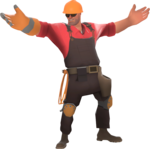

Eliyahu Suskind, 3/3/2023, Revision 1

clc       % clear command window
clear     % clear MATLAB workspace

### Set Up Control System

% Set-up arduino
[robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO('COM13');

Updating server code on board Uno (COM13). This may take a few minutes.


Output argument "rawRangeIn" (and possibly others) not assigned a value in the execution with "SharpIR>SETUPARDUINO"
function.


% Turn board LED on and off to signal program has started
blink(robotArduino, blinkLED, 5);
disp('Warning! Data Collection Active!')

mymode = input("Enter 0 for data collection mode, 1 for obj detection mode.")

if mymode == 0
nTests = input(['Enter number of range test postions, ' 'followed by enter: '])
clc 
end

% Create a variable to hold experimental position data
positionData = zeros(nTests, 2);

r = rateControl(0.1);   % create a 0.1 hz loop rate
reset(r);               % reset loop to time zero

### Run Control Loop

% MODE 0: Data Collection
if mymode == 0
controlFlag = 1;                     
while (controlFlag < nTests+1)

    % Record Data
    rangeData = SENSE(robotArduino, rawRangeIn);

    % Store recorded data
    positionData(controlFlag, 1) = input('Enter center distance in cm: ');
    gtest=input('Move sharp to new range, type G, then hit enter ', 's');
    positionData(controlFlag, 2) = rangeData;
    blink(robotArduino, blinkLED, 1);
    waitfor(r);
    controlFlag = controlFlag+1;

end
end

% MODE 1: Hole detection
if mymode == 1

% Take baseline reading
fakeVariable = input("Press Enter When Ready to Take Baseline","s");
baselineRange = SENSE(robotArduino, rawRangeIn);

% Detect whether hole or obj exists by comparing baseline with current
% reading. Use acceptable deviation in voltage of 0.005
while True
currRange = SENSE(robotArduino, rawRangeIn)
if (currRange > baselineRange + 0.005)
   or (currRange < baselineRange - 0.005)
disp("Object Detected.")
else
disp("Hole Detected.")
end
end
end

### Mission data processing

if mymode == 0

% Plot recorded distance in volts vs actual position in cm
plot(positionData(:,1), positionData(:,2), '-*')
xlabel('Actual Position (cm)')
ylabel('Measured Position (v)')
title("Actual Position vs Recorded Position")
grid

end

### Clean and Shutdown

End program by clearing arduino object and command window

clc
disp('Arduino program has ended');
clear robotArduino
beep

### Robot Functions

function [robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO(COMPORT)
% Purpose: configure and create a global arduino object
% Input: COMPORT is COM port of arduino as string
% Output: arduinoCont is arduino obj, myServo is servo obj, LED is LED pin
    
% create global arduino obj
robotArduino = arduino(COMPORT, 'Uno', 'Libraries', 'Servo');

% configure pin 13 for indicator LED
blinkLED = 'D13';
configurePin(robotArduino, blinkLED, 'DigitalOutput');

% configure A2 pin as analog input for Sharp IRs
rawRangeIn = 'A2';
configurePin(robotArduino, rawRangeIn, 'AnalogInput');


end

function [] = blink(a, LED, n)
% Purpose: blink indicator LED
% Inputs: a is arduino obj, LED is LED pin, n is number of blinks as int

    for bIndex = 1:n
        writeDigitalPin(a, LED, 0);
        pause(0.2);
        writeDigitalPin(a, LED, 1);
        pause(0.2);
    end

end

### Sense Functions

function rangeData = SENSE(robotArduino, rawRangeIn)
% Purpose: Take distance scan with IR sensors.
% Input: robotArduino is the global arduino obj, rawRangIn are the IR
% sensor objects.
% Output: rangeData is the recorded distance reading made.
    rangeData = [readVoltage(robotArduino, rawRangeIn1), readVoltage(robotArduino, rawRangeIn2), readVoltage(robotArduino, rawRangeIn3), readVoltage(robotArduino, rawRangeIn4), readVoltage(robotArduino, rawRangeIn5)]; 
end